# Laplace Transform Lab: Solving ODEs using Laplace Transform in MATLAB

This lab will teach you to solve ODEs using a built in MATLAB Laplace transform function `laplace`. Also in this lab, you will write your own ODE solver using Laplace transforms and check whether the result yields the correct answer.

You will learn how to use the `laplace` routine. 

There are five (5) exercises in this lab that are to be handed in. Write your solutions in the template, including appropriate descriptions in each step. Save the m-file and submit it on Quercus.

Include your name and student number in the submitted file.

MAT292, Fall 2018, Stinchcombe & Khovanskii, modified from MAT292, Fall 2017, Stinchcombe & Sinnamon, modified from MAT292, Fall 2015, Sousa, based on MAT292, Fall 2013, Sinnamon & Sousa

## Student Information

## Using symbolic variables to define functions

Recall the use of symbolic variables and function explained in the MATLAB assignment #2.

syms t s x y

f = cos(t)

$$f = \cos\left(t\right)$$

h = exp(2*x)

$$h = {\mathrm{e}}^{2\,x}$$

## Laplace transform and its inverse

% The routine |laplace| computes the Laplace transform of a function

F=laplace(f)

$$F = \frac{s}{s^{2}+1}$$

By default it uses the variable `s` for the Laplace transform But we can specify which variable we want:

H=laplace(h)

$$H = \frac{1}{s-2}$$

laplace(h,y)

$$ans = \frac{1}{y-2}$$


% Observe that the results are identical: one in the variable |s| and the
% other in the variable |y|

We can also specify which variable to use to compute the Laplace transform:

j = exp(x*t)

$$j = {\mathrm{e}}^{t\,x}$$

laplace(j)

$$ans = \frac{1}{s-x}$$

laplace(j,x,s)

$$ans = \frac{1}{s-t}$$


% By default, MATLAB assumes that the Laplace transform is to be computed
% using the variable |t|, unless we specify that we should use the variable
% |x|

We can also use inline functions with `laplace`. When using inline functions, we always have to specify the variable of the function.

l = @(t) t^2+t+1

l = function_handle with value:
    @(t)t^2+t+1


laplace(l(t))

$$ans = \frac{s+1}{s^{2}}+\frac{2}{s^{3}}$$

MATLAB also has the routine `ilaplace` to compute the inverse Laplace transform

ilaplace(F)

$$ans = \cos\left(t\right)$$

ilaplace(H)

$$ans = {\mathrm{e}}^{2\,t}$$

ilaplace(laplace(f))

$$ans = \cos\left(t\right)$$

If `laplace` cannot compute the Laplace transform, it returns an unevaluated call.

g = 1/sqrt(t^2+1)

$$g = \frac{1}{\sqrt{t^{2}+1}}$$

G = laplace(g)

$$G = \mathrm{laplace}\left(\frac{1}{\sqrt{t^{2}+1}},t,s\right)$$

But MATLAB "knows" that it is supposed to be a Laplace transform of a function. So if we compute the inverse Laplace transform, we obtain the original function

ilaplace(G)

$$ans = \frac{1}{\sqrt{t^{2}+1}}$$

The Laplace transform of a function is related to the Laplace transform of its derivative:

syms g(t) s
laplace(diff(g,t),t,s)

$$ans = s\,\mathrm{laplace}\left(g\left(t\right),t,s\right)-g\left(0\right)$$

## Exercise 1

Objective: Compute the Laplace transform and use it to show that MATLAB 'knows' some of its properties.

Details: 

(a) Define the function `f(t)=exp(2t)*t^3`, and compute its Laplace transform `F(s)`. (b) Find a function `f(t)` such that its Laplace transform is  `(s - 1)*(s - 2))/(s*(s + 2)*(s - 3)` (c) Show that MATLAB 'knows' that if `F(s)` is the Laplace transform of  `f(t)`, then the Laplace transform of `exp(at)f(t)` is `F(s-a)` 

(in your answer, explain part (c) using comments). 

Observe that MATLAB splits the rational function automatically when solving the inverse Laplace transform.

%(A) 
f = @ (t) exp(2*t)*t^3

f = function_handle with value:
    @(t)exp(2*t)*t^3


laplace(f, t, s)

$$ans = \frac{6}{{\left(s-2\right)}^{4}}$$


%(B)
f_1b = @ (s) ((s - 1)*(s - 2))/(s*(s + 2)*(s - 3))

f_1b = function_handle with value:
    @(s)((s-1)*(s-2))/(s*(s+2)*(s-3))


F_1b = ilaplace(f_1b, t, s)

$$F\_1b = \frac{\delta (s)\,\left(s-1\right)\,\left(s-2\right)}{s\,\left(s+2\right)\,\left(s-3\right)}$$


%(C)
syms f(t) a

F = laplace(f(t))

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

F1 = laplace(exp(a*t)*f(t))

$$F1 = \mathrm{laplace}\left(f\left(t\right),t,s-a\right)$$

 F(s) is the laplace transform of f(t). When we compute F1 as above, we get back laplace(f(t), t, s-a), 

 which is F(s-a), as expected. 

## Heaviside and Dirac functions

These two functions are builtin to MATLAB: `heaviside` is the Heaviside function `u_0(t)` at `0`

To define `u_2(t)`, we need to write

f=heaviside(t-2)

$$f = \mathrm{heaviside}\left(t-2\right)$$

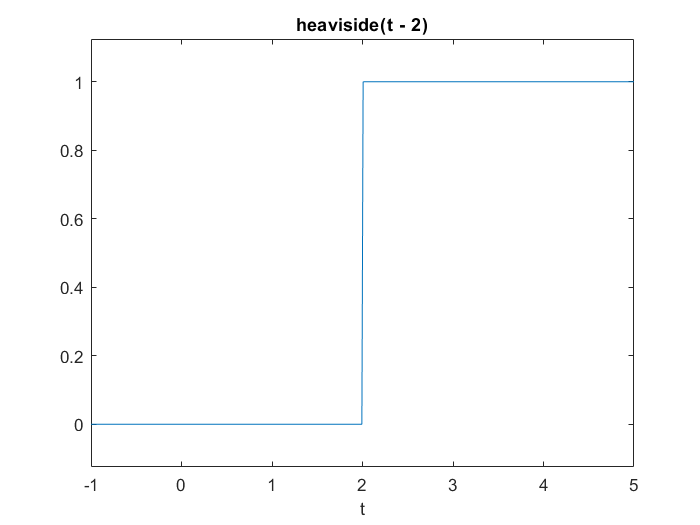

ezplot(f,[-1,5])


% The Dirac delta function (at |0|) is also defined with the routine |dirac|

g = dirac(t-3)

$$g = \delta (t-3)$$


% MATLAB "knows" how to compute the Laplace transform of these functions

laplace(f)

$$ans = \frac{{\mathrm{e}}^{-2\,s}}{s}$$

laplace(g)

$$ans = {\mathrm{e}}^{-3\,s}$$

## Exercise 2

Objective: Find a formula comparing the Laplace transform of a translation of `f(t)` by `t-a` with the Laplace transform of `f(t)`

Details: 

- Give a value to `a`

- Let `G(s)` be the Laplace transform of `g(t)=u_a(t)f(t-a)` and `F(s)` is the Laplace transform of `f(t)`, then find a formula relating `G(s)` and `F(s)`

In your answer, explain the 'proof' using comments.

%Let a = 5
a = 5;
syms f(t), 

F = laplace(f(t))

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

G = laplace((heaviside(t-a))*f(t-a))

$$G = {\mathrm{e}}^{-5\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

 We find that G(s) = exp(-a*s)*F(s).

 This is not a proof, but rather a verification of the fact that when taking the laplace transform of a function multiplied by heaviside(t-a), we get

 exp(-as)*L(f(t)), where L() denotes the laplace transform. 

## Solving IVPs using Laplace transforms

Consider the following IVP, `y''-3y = 5t` with the initial conditions `y(0)=1` and `y'(0)=2`. We can use MATLAB to solve this problem using Laplace transforms:

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown

syms y(t) t Y s

% Then we define the ODE

ODE3=diff(y(t),t,2)-3*y(t)-5*t == 0

$$ODE3 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-5\,t-3\,y\left(t\right)=0$$


% Now we compute the Laplace transform of the ODE.

L_ODE4 = laplace(ODE3)

$$L\_ODE4 = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=0$$


% Use the initial conditions

L_ODE4=subs(L_ODE4,y(0),1)

$$L\_ODE4 = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=0$$

L_ODE4=subs(L_ODE4,subs(diff(y(t), t), t, 0),2)

$$L\_ODE4 = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-2=0$$


% We then need to factor out the Laplace transform of |y(t)|

L_ODE4 = subs(L_ODE4,laplace(y(t), t, s), Y)

$$L\_ODE4 = Y\,s^{2}-s-3\,Y-\frac{5}{s^{2}}-2=0$$

Y=solve(L_ODE4,Y)

$$Y = \frac{s+\frac{5}{s^{2}}+2}{s^{2}-3}$$


% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y = ilaplace(Y)

$$y = \cosh\left(\sqrt{3}\,t\right)-\frac{5\,t}{3}+\frac{11\,\sqrt{3}\,\sinh\left(\sqrt{3}\,t\right)}{9}$$

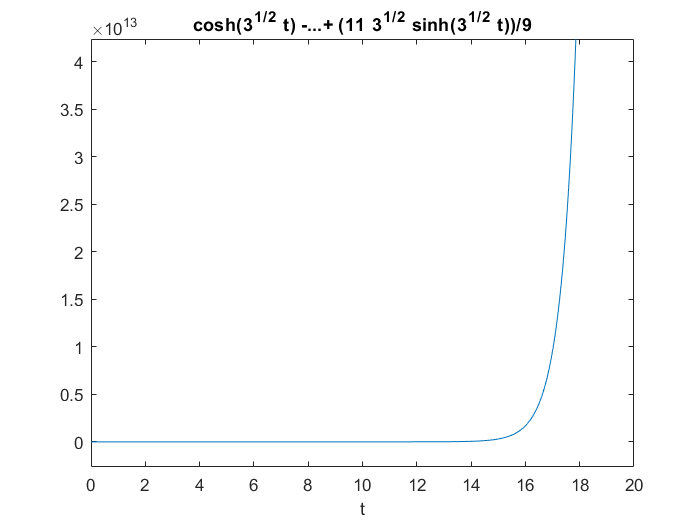


% We can plot the solution

ezplot(y,[0,20])


% We can check that this is indeed the solution

diff(y,t,2)-3*y

$$ans = 5\,t$$

## Exercise 3

Objective: Solve an IVP using the Laplace transform

Details: Explain your steps using comments

- Solve the IVP

- |y'''+2y''+y'+2*y=-cos(t)

- `y(0)=0`, `y'(0)=0`, and `y''(0)=0`

- for `t` in `[0,10*pi]`

- Is there an initial condition for which `y` remains bounded as `t` goes to infinity? If so, find it.

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown

syms y(t) t Y s

% Then we define the ODE

ODE3=diff(y(t),t,3)+ 2*diff(y(t), t, 2) + diff(y(t), t, 1) + 2*y(t) == -cos(t)

$$ODE3 = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=-\cos\left(t\right)$$


% Now we compute the Laplace transform of the ODE.

L_ODE3 = laplace(ODE3)

$$L\_ODE3 = \begin{array}{l} s\,\sigma_{1}-y\left(0\right)-2\,s\,y\left(0\right)-s\,\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+2\,s^{2}\,\sigma_{1}+s^{3}\,\sigma_{1}-2\,\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-s^{2}\,y\left(0\right)-\left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)+2\,\sigma_{1}=-\frac{s}{s^{2}+1}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{laplace}\left(y\left(t\right),t,s\right) \end{array}$$


% Use the initial conditions

L_ODE3=subs(L_ODE3,y(0),0)

$$L\_ODE3 = \begin{array}{l} s\,\sigma_{1}-s\,\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+2\,s^{2}\,\sigma_{1}+s^{3}\,\sigma_{1}-2\,\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)+2\,\sigma_{1}=-\frac{s}{s^{2}+1}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{laplace}\left(y\left(t\right),t,s\right) \end{array}$$

L_ODE3=subs(L_ODE3,subs(diff(y(t), t), t, 0),0)

$$L\_ODE3 = s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{3}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=-\frac{s}{s^{2}+1}$$

L_ODE3=subs(L_ODE3,subs(diff(y(t), t, 2), t, 0),0)

$$L\_ODE3 = s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{3}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=-\frac{s}{s^{2}+1}$$


% We then need to factor out the Laplace transform of |y(t)|

L_ODE3 = subs(L_ODE3,laplace(y(t), t, s), Y)

$$L\_ODE3 = Y\,s^{3}+2\,Y\,s^{2}+Y\,s+2\,Y=-\frac{s}{s^{2}+1}$$

Y=solve(L_ODE3,Y)

$$Y = -\frac{s}{\left(s^{2}+1\right)\,\left(s^{3}+2\,s^{2}+s+2\right)}$$


% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y3 = ilaplace(Y)

$$y3 = \frac{2\,{\mathrm{e}}^{-2\,t}}{25}-\frac{2\,\cos\left(t\right)}{25}+\frac{3\,\sin\left(t\right)}{50}+\frac{t\,\cos\left(t\right)}{10}-\frac{t\,\sin\left(t\right)}{5}$$

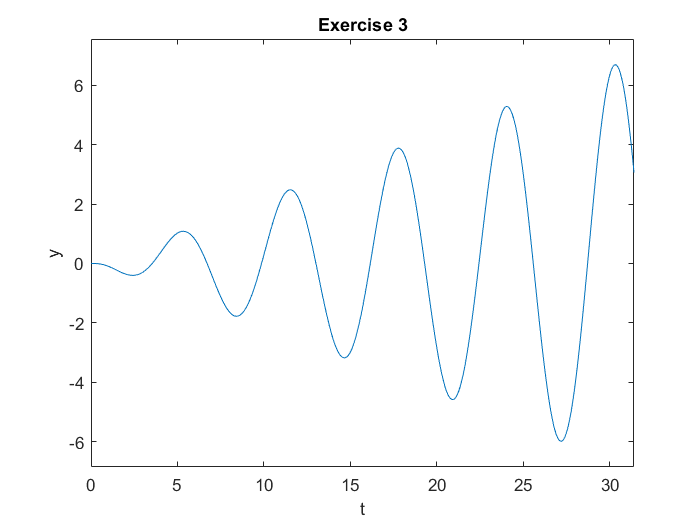


% We can plot the solution

ezplot(y3,[0,10*pi])
xlabel('t')
ylabel('y')
title('Exercise 3')

 We can see that this solution is growing as it is oscillating; this means that there is resonance;

 this means that one of the solutions to the homogenous DE corresponds with the forcing function.

**FIND INITIAL CONDITION:**

The solution to the differential in it's general form (no subbed in initial conditions) is as follows:

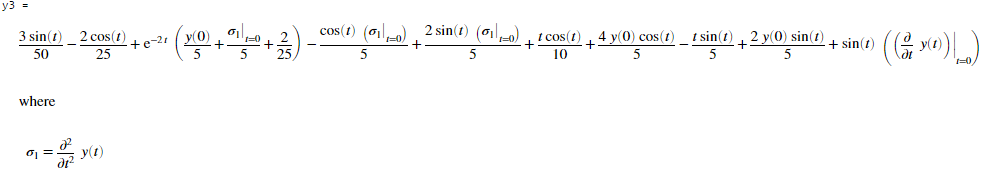

We can see that the unbounded nature comes from the tsin(t) and tcos(t) terms. There is no initial condition coefficient for these terms however, so we conclude that we cannot prevent the resonanace of this functione due to the nature of the forcing function. The forcing function will cause resonance to occur. 

## Exercise 4

Objective: Solve an IVP using the Laplace transform

Details: 

- Define 

- `g(t) = 3 if 0 < t < 2`

- `g(t) = t+1 if 2 < t < 5`

- `g(t) = 5 if t > 5`

- Solve the IVP

- `y''+2y'+5y=g(t)`

- `y(0)=2 and y'(0)=1`

- Plot the solution for `t` in `[0,12]` and `y` in `[0,2.25]`.

In your answer, explain your steps using comments.

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown

syms y(t) t Y s

% Then we define the RHS of the ODE:

ODE4 = 3*heaviside(t) + (t-2)*heaviside(t-2) + (4-t)*heaviside(t-5)

$$ODE4 = 3\,\mathrm{heaviside}\left(t\right)+\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\mathrm{heaviside}\left(t-5\right)\,\left(t-4\right)$$


% Now we compute the Laplace transform of the ODE.

L_ODE4 = laplace(ODE4)

$$L\_ODE4 = \frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+\frac{3}{s}-\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}$$


%Definition and Laplace transform of left hand side:
lhs = diff(y(t), t, 2) + 2*diff(y(t), t, 1) + 5*y(t)

$$lhs = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+2\,\frac{\partial }{\partial t}y\left(t\right)+5\,y\left(t\right)$$

L_LHS = laplace(lhs)

$$L\_LHS = 2\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-2\,y\left(0\right)-s\,y\left(0\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+5\,\mathrm{laplace}\left(y\left(t\right),t,s\right)$$


% Use the initial conditions:

L_LHS=subs(L_LHS,y(0),0)

$$L\_LHS = 2\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+5\,\mathrm{laplace}\left(y\left(t\right),t,s\right)$$

L_LHS=subs(L_LHS,subs(diff(y(t), t), t, 0),1)

$$L\_LHS = 2\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+5\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-1$$


%Define all Laplace transformed variables on left  = 0:
L_4 = L_LHS - L_ODE4

$$L\_4 = 2\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\frac{3}{s}+\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}+5\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-1$$


% We then need to factor out the Laplace transform of |y(t)|

L_4 = subs(L_4,laplace(y(t), t, s), Y)

$$L\_4 = 5\,Y+2\,Y\,s-\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+Y\,s^{2}-\frac{3}{s}+\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}-1$$

Y4=solve(L_4,Y)

$$Y4 = \frac{\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+\frac{3}{s}-\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}+1}{s^{2}+2\,s+5}$$


% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y4 = ilaplace(Y4, s ,t)

$$y4 = \begin{array}{l} \mathrm{heaviside}\left(t-2\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{2-t}\,\left(\cos\left(2\,t-4\right)-\frac{3\,\sin\left(2\,t-4\right)}{4}\right)}{25}-\frac{12}{25}\right)-\mathrm{heaviside}\left(t-5\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{5-t}\,\left(\sigma_{2}-\frac{3\,\sigma_{1}}{4}\right)}{25}-\frac{27}{25}\right)-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\frac{\sin\left(2\,t\right)}{2}\right)}{5}+\frac{\sin\left(2\,t\right)\,{\mathrm{e}}^{-t}}{2}+\mathrm{heaviside}\left(t-5\right)\,\left(\frac{{\mathrm{e}}^{5-t}\,\left(\sigma_{2}+\frac{\sigma_{1}}{2}\right)}{5}-\frac{1}{5}\right)+\frac{3}{5}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,t-10\right)\\ \sigma_{2}=\cos\left(2\,t-10\right) \end{array}$$

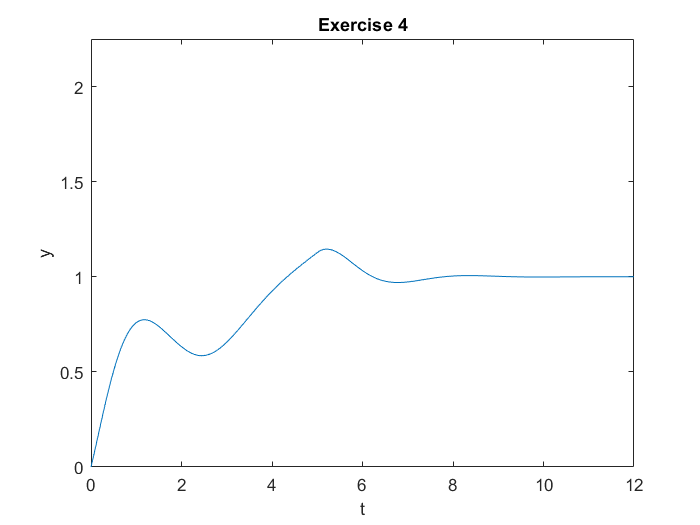


% We can plot the solution

ezplot(y4,[0, 12, 0, 2.25])
xlabel('t')
ylabel('y')
title("Exercise 4")

 We can see that the graph increases till y = 1 and at t ~ 7, stabilizes at y = 1.

 The forcing function acts on the graph at the times describes above, causing a  fluctuation in the position. We note that this is a very realistic scenario, in which a force is applied to some system in intervals, and the force is dependent on time. 

## Exercise 5

Objective: Solve an IVP with a periodic function using the Laplace transform.

Details:

- Follow the instructions on the website  [http://instruct.math.lsa.umich.edu/lecturedemos/ma216/docs/7_5/](http://instruct.math.lsa.umich.edu/lecturedemos/ma216/docs/7_5/)

- Do the part labelled `Outside of Lecture`

- Note that `u(t-a)` is the Heaviside function `u_a(t)` defined in our textbook

- Check Theorem 5.5.3 (page 349) to know how to define the Laplace transform of a periodic function like the one in this exercise (and check the function `int` on MATLAB for symbolic integration).

- Hint: Use only the second-order DE given on the linked website

- Hint: You should use the numbers provided (the less precise ones)

- Hint: You should obtain an exact solution. In the process, you should need symbolic integration(s).

%Converting the system of differential equations to a
% second order differential equation, we get:
% y'' + y'(0.54) + (0.02)y = I(t)

syms Y y(t) s t f(t)

%Parameters:
k1 = 0.12;
k2 = 0.38;
k3 = 0.04;
I0 = 24;
t0 = 6;
t1 = 24;
T = t0 + t1; % this is the period of the forcing function

%LHS:
LHS = diff(y(t), t, 2) + (0.54)*diff(y(t), t, 1) + 0.02*y(t)

$$LHS = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{27\,\frac{\partial }{\partial t}y\left(t\right)}{50}+\frac{y\left(t\right)}{50}$$


%RHS 
RHS = f(t)  %Forcing function 

$$RHS = f\left(t\right)$$


%Define ODE  = LHS - RHS = 0

ODE5 = LHS - RHS

$$ODE5 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{27\,\frac{\partial }{\partial t}y\left(t\right)}{50}-f\left(t\right)+\frac{y\left(t\right)}{50}$$


%Laplace of ODE = LHS-RHS:

L_ODE5 = laplace(ODE5)

$$L\_ODE5 = \frac{27\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}-\frac{27\,y\left(0\right)}{50}-s\,y\left(0\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\mathrm{laplace}\left(f\left(t\right),t,s\right)+\frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}$$


% Sub in the initial conditions:

L_ODE5 = subs(L_ODE5, y(0), 0)

$$L\_ODE5 = \frac{27\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\mathrm{laplace}\left(f\left(t\right),t,s\right)+\frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}$$

L_ODE5 = subs(L_ODE5, subs(diff(y(t), t), t, 0), 0)

$$L\_ODE5 = \frac{27\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-\mathrm{laplace}\left(f\left(t\right),t,s\right)+\frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}$$


%Sub in the forcing function using theorem 5.5.3:
L_ODE5 = subs(L_ODE5,subs(laplace(f(t),t,s)),int(exp(-s*x)*((k1*I0)/t0),x,0,t0)/(1-exp(-s*T)))

$$L\_ODE5 = \frac{27\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+\frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{50}-\frac{12\,\left({\mathrm{e}}^{-6\,s}-1\right)}{25\,s\,\left({\mathrm{e}}^{-30\,s}-1\right)}$$


%Sub in Y for laplace(y(t), t, s):

L_ODE5 = subs(L_ODE5, laplace(y(t), t, s), Y)

$$L\_ODE5 = \frac{Y}{50}+\frac{27\,Y\,s}{50}+Y\,s^{2}-\frac{12\,\left({\mathrm{e}}^{-6\,s}-1\right)}{25\,s\,\left({\mathrm{e}}^{-30\,s}-1\right)}$$


%Solve for Y:

Y=solve(L_ODE5,Y)

$$Y = \frac{12\,\left({\mathrm{e}}^{-6\,s}-1\right)}{25\,s\,\left({\mathrm{e}}^{-30\,s}-1\right)\,\left(s^{2}+\frac{27\,s}{50}+\frac{1}{50}\right)}$$


% We now need to use the inverse Laplace transform to 
% obtain the solution to the original IVP

y5 = ilaplace(Y, s ,t)

$$y5 = \begin{array}{l} \frac{12\,\mathrm{heaviside}\left(t-6\right)\,\left(50\,\sigma_{1}-\frac{100\,{\mathrm{e}}^{3-\frac{t}{2}}\,\left({\left({\mathrm{e}}^{-15}\right)}^{\sigma_{1}}-1\right)}{\sigma_{3}}+\frac{1250\,{\mathrm{e}}^{\frac{6}{25}-\frac{t}{25}}\,\left({\left({\mathrm{e}}^{-\frac{6}{5}}\right)}^{\sigma_{1}}-1\right)}{\sigma_{2}}\right)}{25}-24\,\left\lfloor -\frac{t}{30}\right\rfloor +\frac{48\,{\mathrm{e}}^{-\frac{t}{2}}\,\left({\left({\mathrm{e}}^{-15}\right)}^{\left\lfloor -\frac{t}{30}\right\rfloor }-1\right)}{\sigma_{3}}-\frac{600\,{\mathrm{e}}^{-\frac{t}{25}}\,\left({\left({\mathrm{e}}^{-\frac{6}{5}}\right)}^{\left\lfloor -\frac{t}{30}\right\rfloor }-1\right)}{\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\left\lfloor \frac{1}{5}-\frac{t}{30}\right\rfloor \\ \sigma_{2}=23\,\left({\mathrm{e}}^{6/5}-1\right)\\ \sigma_{3}=23\,\left({\mathrm{e}}^{15}-1\right) \end{array}$$

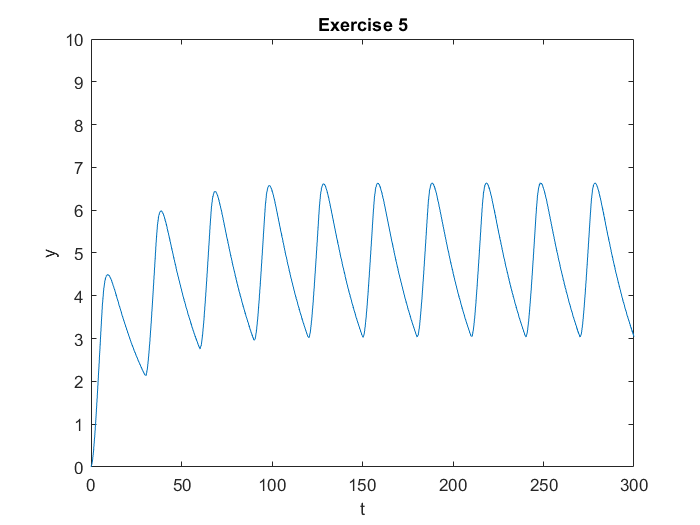


%Plot:

ezplot(y5,[0, 300, 0, 10])
ylabel('y')
xlabel('t')
title('Exercise 5')

We can see that the solutions grows to a  certain average value, about 5, then oscillates. 

This is consistent with the results on the website. 